## Modulación FM

## Definiciones


$$f_c =\textrm{frecuencia}\;\textrm{central}$$



$$K_f =\textrm{desviacion}\;\textrm{de}\;\textrm{frecuencia}\;\max$$



$$m\left(t\right)=\textrm{señal}\;\textrm{moduladora}$$



$$a\left(t\right)=\int m\left(t\right)$$



$$\underset{\theta \left(t\right)}{\rho_{\textrm{FM}} =\textrm{Acos}\underbrace{\left(2\pi f_c t+2\pi K_f a\left(t\right)\right)} }$$


Fase instantanea


$$\frac{d\theta(t)}{dt*2\pi}=f_c+K_fa'(t)=f_c+K_fm(t)$$


Indice de modulación $\beta =\frac{f_d }{f_m }$ para el caso de portadora con amplitud unitaria queda en terminos de $K_f$

$\beta =\frac{K_f }{f_m }$ donde $f_m$ es la frecuencia maxima de $m\left(t\right)$

## Modulación por tono

Se desea una frecuencia en un rango de $20\pm 2\textrm{hz}$ $f_c \pm K_f$. $K_f =2$

Con la señal moduladora $\cos \left(2\pi 2\right)$. $f_m =2$. Por lo tanto $\beta =\frac{K_f }{f_m }=1$

%definicion de ejes
time = -2:1/256:2;
freq = -32:1/16:32;

%
fmod = 2; % frecuencia moduladora maxima a 2 hz
kf   = 2; % variación 
fc   = 20; % frecuencia central portadora

wm = 2*pi*fmod; % moduladora en rad
%m(t) -> cos(wm*time)
a_t = 1/wm*sin(wm*time); %a(t) = integral m(t)
theta = 2*pi*(fc*time+kf*a_t); %
fm1=cos(theta);

Codigo para su grafica con puntos maximos en frecuencia

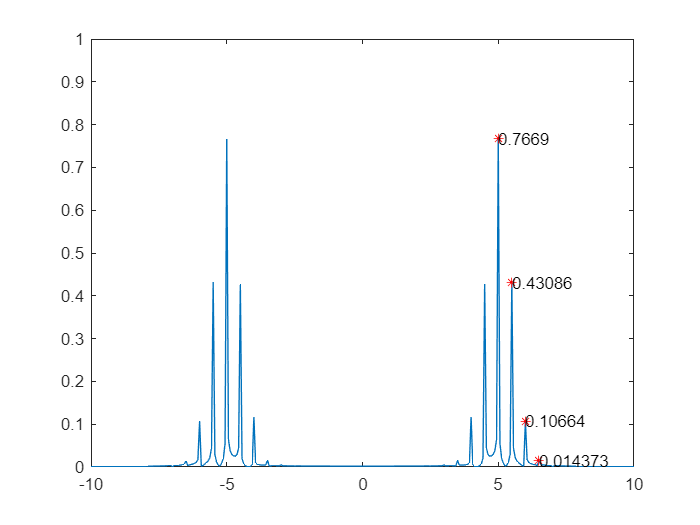

%plot stuff
figure(1);
fm1 = abs(ttof(fm1))/(.5*length(freq)); % normalizing with observation windows
TF = islocalmax(fm1);
key_freq   = freq(TF);
value_freq = fm1(TF);
key_freq = key_freq(21:24);
value_freq = value_freq(21:24);
plot(freq,fm1,key_freq,value_freq,'r*')
text(key_freq,value_freq,string(value_freq))
axis([-10 10 0 1])

Dicho comportamiento se debe al ancho de banda en FM que esta relacionado con $J_n \left(\beta \right)$ la cual es la función de bessel y el ancho de banda esta dado por $\rho {\;}_{\textrm{FM}} =A\sum_{-\infty }^{\infty } J_n \left(\beta \right)c\textrm{os}\left(w_c +n\omega_m \right)t$  . Las funciones de bessel pesan a las frecuencias. 

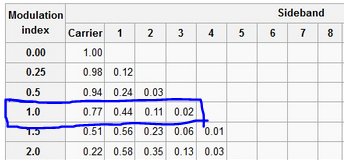

## Demodulacion 

Tenemos que derivar la señal de FM


$$\rho_{\textrm{FM}} =\textrm{Acos}\left(\omega_c t+k_f \int m\left(\alpha \right)d\alpha \right)$$



$${\frac{d}{\textrm{dt}}\;\rho }_{\textrm{FM}} =\frac{d}{\textrm{dt}}\textrm{Acos}\left(\omega_c t+k_f \int m\left(\alpha \right)d\alpha \right)$$



$${\frac{d}{\textrm{dt}}\;\rho }_{\textrm{FM}} =A\left\lbrack \omega_c +k_F m\left(t\right)\right\rbrack \sin \left(\omega_c t+k_f \int m\left(\alpha \right)d\alpha \right)$$
 

La señal queda de FM y AM, entonces la paso por un valor al cuadrado o abs para obtener puros valores positivos, la señal quedaria solamente como un detector de envolvente, lo filtro y recupero la señal original.

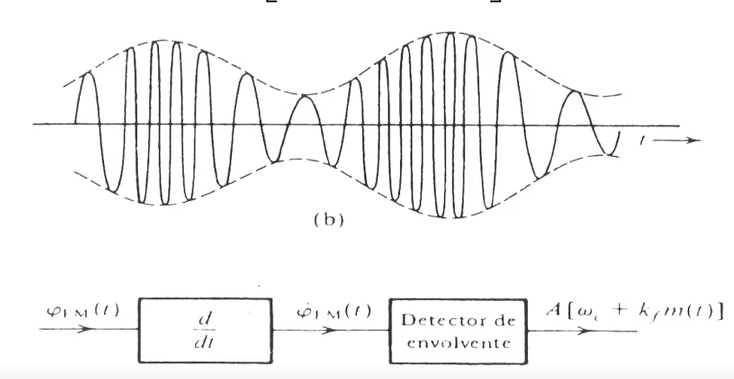

Para poder derivar de manera mas sencilla y sin tanto gasto de memoria, podemos recordar que la derivación en frecuencia es $j\omega$ por lo que solo queda aplicar un filtro derivador a la señal para que surge el efecto deseado. 

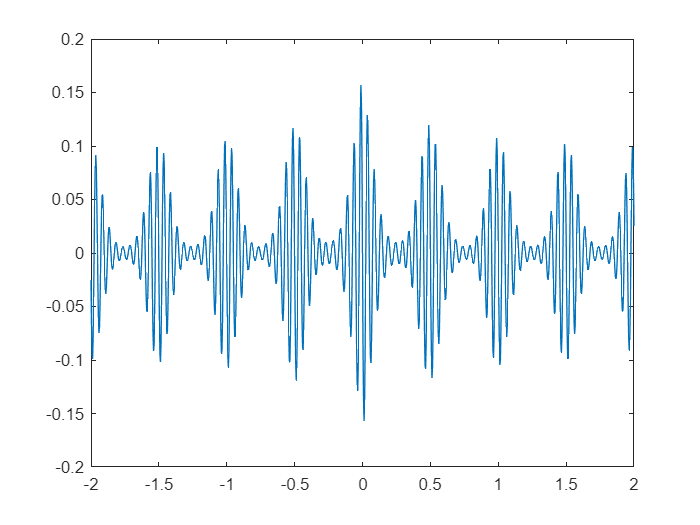

filtro_derivador = zeros(1,length(freq));
filtro_derivador = 1i*2*pi*freq;
fm1_df = fm1.*filtro_derivador; % señal deriva
fm1_dt = real(ftot(fm1_df)); % Señal derivada en tiempo conversion FM-AM 
fm1_dt_abs = abs(fm1_dt);
figure(2);
plot(time,fm1_dt); % señal derivada

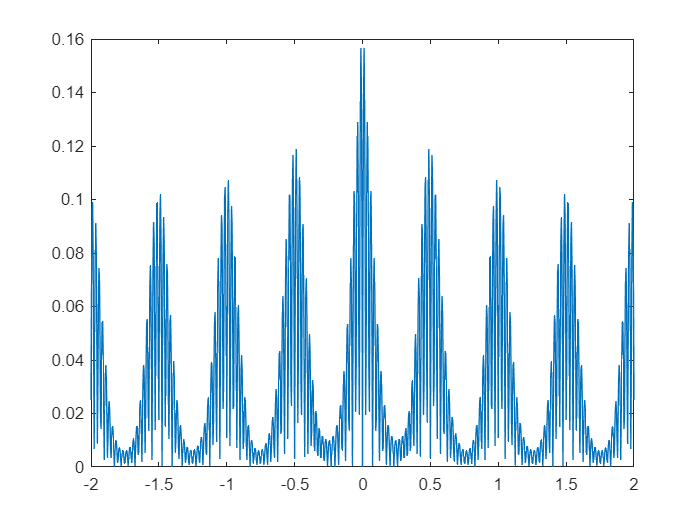

figure(3);
plot(time,fm1_dt_abs);

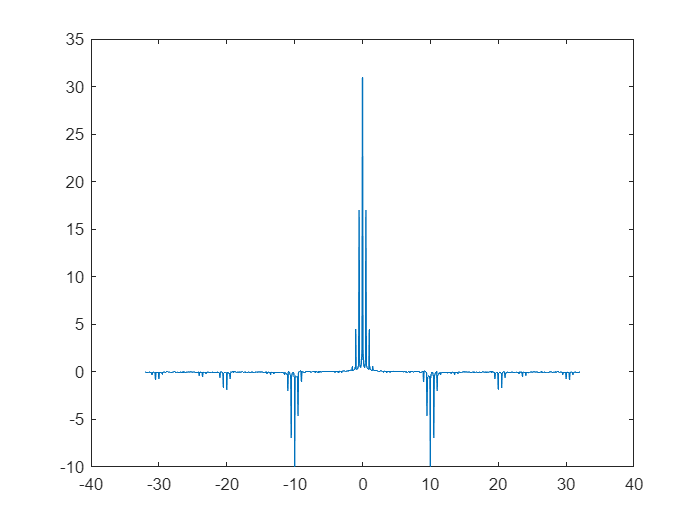

fm1_dt_abs_f = real(ttof(fm1_dt_abs));
plot(freq,fm1_dt_abs_f);

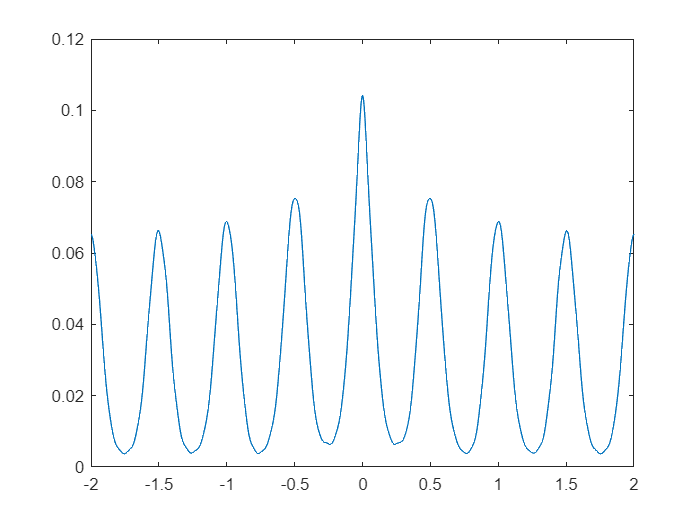

lowpassFilter = zeros(1,length(freq));
%make 1 the range of values that wanna be filtered
%interpolation of a frecuency for obtain more samples as nyquist say
lowpassFilter(find(freq==interp1(freq,freq,-4,'nearest')):find(freq==interp1(freq,freq,4,'nearest'))) = 1;
Demodule_f = lowpassFilter.*fm1_dt_abs_f; % applying filter
Demodule_t = real(ftot(Demodule_f)); % convert to time
figure(5);
plot(time,Demodule_t);

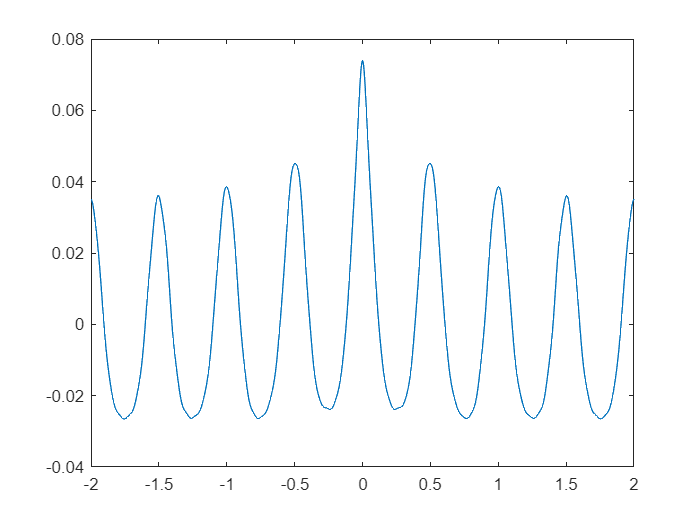

figure(6);
Demode_FM  = Demodule_t-mean(Demodule_t); % remove DC constant
plot(time,Demode_FM);